# Hunt for a sensible LQI solution - part 1

Load the Linearised quadcopter+pendulum model

load('bh_SAVED_LIN_PLANT.mat')
size(my_LIN_PLANT)

State-space model with 3 outputs, 4 inputs, and 18 states.


## Control design:

We'll use the approach described by the LQI() function, ie::

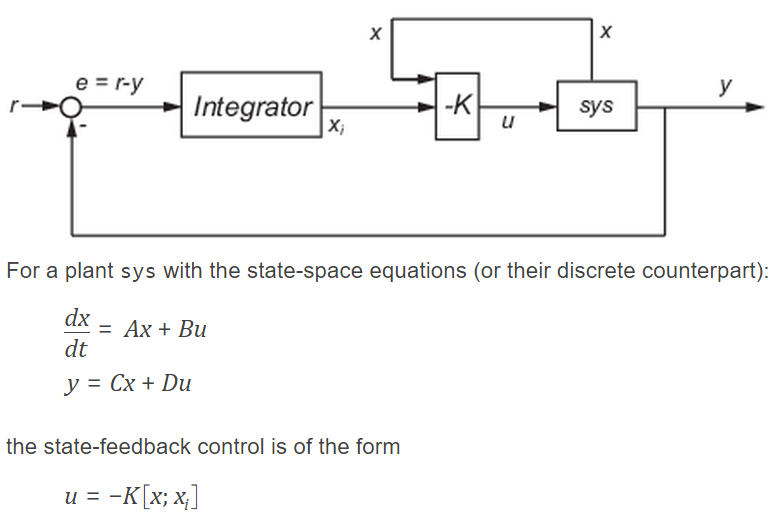

Note that:  

- 
$$K\in R^{N_u \times \left(N_x +N_y \right)}$$


A = my_LIN_PLANT.A;
B = my_LIN_PLANT.B;
C = my_LIN_PLANT.C;

Nx = size(A,1);  Nu = size(B,2);  Ny = size(C,1);

Now design a full state feedback controller using `LQI()`. NOTE the following:

- you will need to experiment with the Q,R weighting matrices


res_T.tf_is_good   = false;
res_T.K            = [];
res_T.p            = [];
res_T.tf_all_p_neg = false;
res_T.p_first      = 0;
res_T.K_av         = 0;
res_T.g_Q          = 0;
res_T.g_R          = 0;
res_array   = repmat(res_T, [1,1]);

gg = 6.4e5; % OK
%gg = 645019;
       [K, p_lqi] = LOC_do_LQI(my_LIN_PLANT, 1, gg, Nx, Ny, Nu);

Error using ss/lqi (line 115)
Cannot compute the stabilizing Riccati solution S for the LQR design. 
This could be because: 
  * R is singular, 
  * [Q N;N' R] needs to be positive definite, 
  * The E matrix in the state equation is singular.

Error in zaz>LOC_do_LQI (line 51)
    [K,~,~] = lqi(my_LIN_PLANT,Q,R,[]);

       res_array(1).tf_is_good = true;
       res_array(1).K = K;
       res_array(1).p = p_lqi;
       if( all( real(p_lqi) < 0 ))
           res_array(1).tf_all_p_neg = true;           
       end
       res_array(1).p_first = p_lqi(1);
       
       res_array(1).K_av = mean(abs(K), 'all');
       res_array(1).g_Q  = 1;
       res_array(1).g_R  = gg;       
       
figure;
heatmap(res_array.K,'ColorMap',jet(20));

res_array.p

mean(abs(res_array.K), 'all')

And we're done

fprintf('\n ... we are finished here ! \n')

**TARGETS are:**

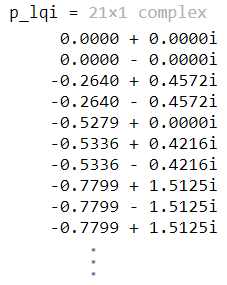   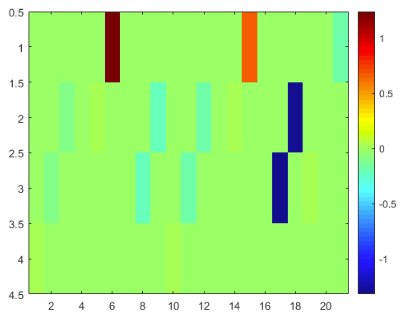

# Local Subfunctions only beyond this point

function [K, p_lqi] = LOC_do_LQI(my_LIN_PLANT, g_Q, g_R, Nx, Ny, Nu)

    tmp = g_Q*[ones(1, Nx+Ny)];
    
   tmp(19:21) = [2,2,1500];
    %tmp(19:21) = [1,1,1];    
    Q   = diag(tmp); 
    tmp = g_R*[1,1,1,1];
    R = diag(tmp); 
    
    [K,~,~] = lqi(my_LIN_PLANT,Q,R,[]);

    
    A = my_LIN_PLANT.A;
    B = my_LIN_PLANT.B;
    C = my_LIN_PLANT.C;
    
    A_hat = [  A,   zeros(Nx,Ny);
              -C,   zeros(Ny,Ny) ];
      
    B_hat = [ B;
              zeros(Ny,Nu) ];
          
    p_lqi = esort( pole( ss((A_hat-B_hat*K),[],[],[]) ) );
    
end